# EFMouse: 4xLumbar with craniotomy montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 4xLumbar with craniotomy montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver getDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '4xLumbar_cran';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse/4xLumbar_cran'; % Results and the object (4xLumbar_cran.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o

Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

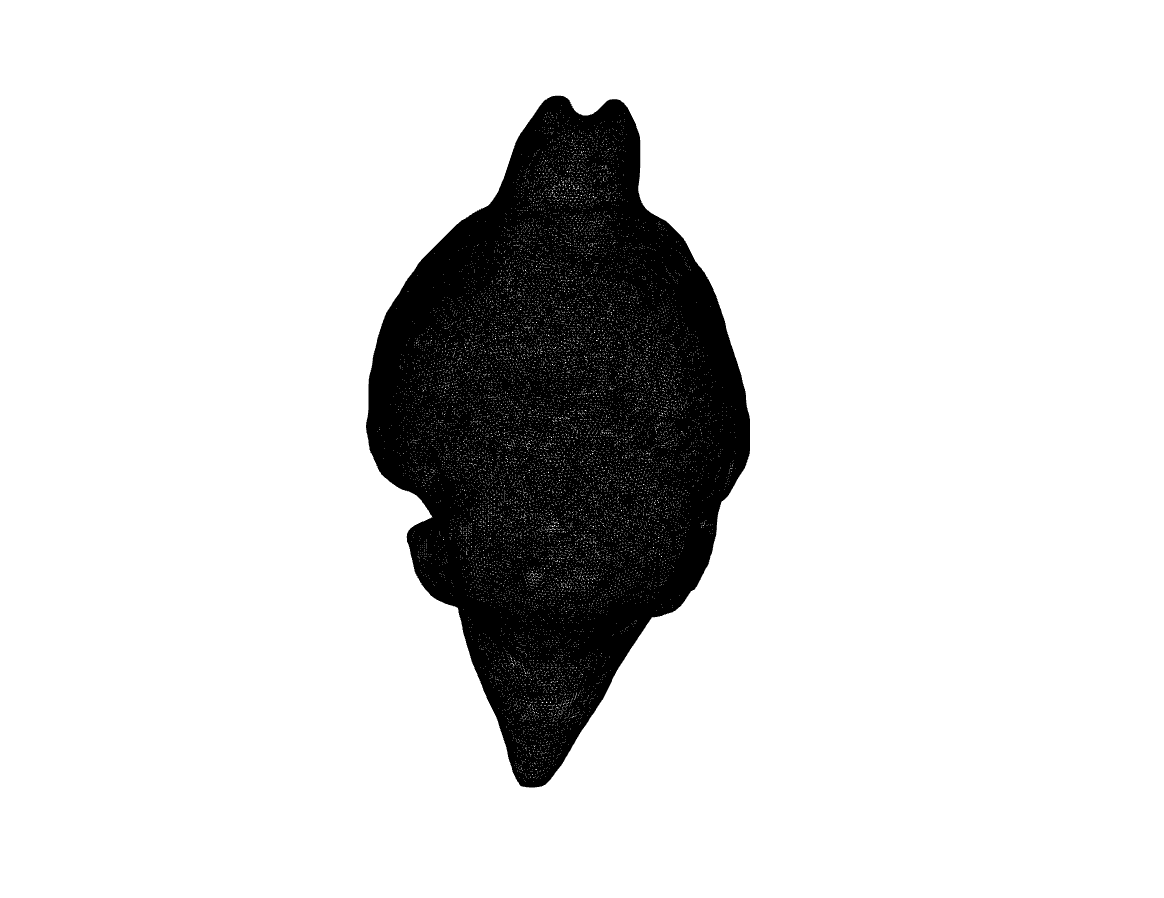

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 4x1 center-surround stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anterior",current = 0.05,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = 0.05,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lateral",current = 0.05,type="surface",shape="circle",center= [-6,27.5,4],radius=0.6, thickness=1);
o.addElectrode(tag = "Medial",current = 0.05,type="surface",shape="circle",center= [-1,27.5,6],radius=0.6, thickness=1);
%TODO: change this to rectangle. Use the same position as in the original 4x1   
o.addElectrode(tag = "Lumbar",current = -0.2,type="surface",shape="circle",center= [-1,-10,10],radius=0.6, thickness=1);

Add a craniotomy between the stimulation electrodes. Select the material replacing the space where skin and bone were removed. Here, we simulate the presence of a glass coverslip that stop the csf to flow to the skin.  

o.addCraniotomy(tag = "left",center=[-3.5,27.5,6],radius=1.5,material=["air","csf"]);

To update the model with the electrodes, we run the pipeline to Stage.MESH. With `show=true`, this also opens a figure for inspection of the mesh:

o.run(targetStage=Stage.MESH,show=true)

Stage MESH already completed.


This mesh shows the electrodes in red (anode) and blue (cathode). For the craniotomy, the two tissue types that have been removed (skin and bone) are shown in cyan and magenta. 

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in 4*x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

This file can be opened in the getDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

plotEf(o,type='eX',percentile=98, tissue='gray');
plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. In creating the craniotomy, it was labeled after the tag chosen for the craniotomy and the name of the tissue that was removed. So `leftbone ` is the part of the mouse that was removed from the bone to create the craniotomy.

See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o,["skin" "gray" "leftbone"])

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2014), for definitions of relative focality and homogeneity.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  %Left/right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Z
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.
% Rotate and zoom to view the (yellow) box ROI underneath the return electrode
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)
summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=75);
% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir=fullfile(tempdir,"efmouse/4xLumbar_cran"),ID='4xLumbar_cran')